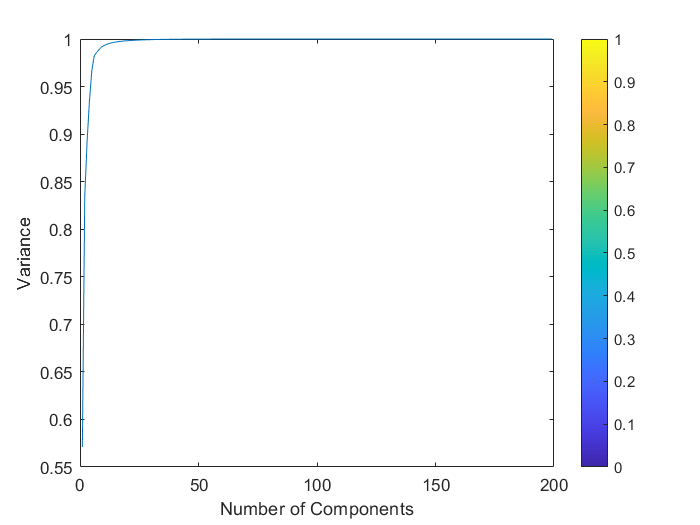

trialInfo.tBefore = -2e2;
trialInfo.tAfter  = 0;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;


driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32

dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;
driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);

data_twoDrives{2} = data;

% we are gonna compress the data
data_two_drives = cat(2,data_twoDrives{1},data_twoDrives{2});

%we have trials by electrodes by time series

%then we do PCA
ti = 4;
data_temp = squeeze(data_two_drives(ti,:,:));

%data_temp = reshape(data_two_drives,243,[]);

[coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables

plot(cumsum(latent)/sum(latent))
xlabel('Number of Components')
ylabel('Variance')
colorbar

%the effective dimensionality
%latent values
lamda_j = latent / sum(latent);
dim_eff = 1 / sum(lamda_j.^2)

dim_eff = 2.4882

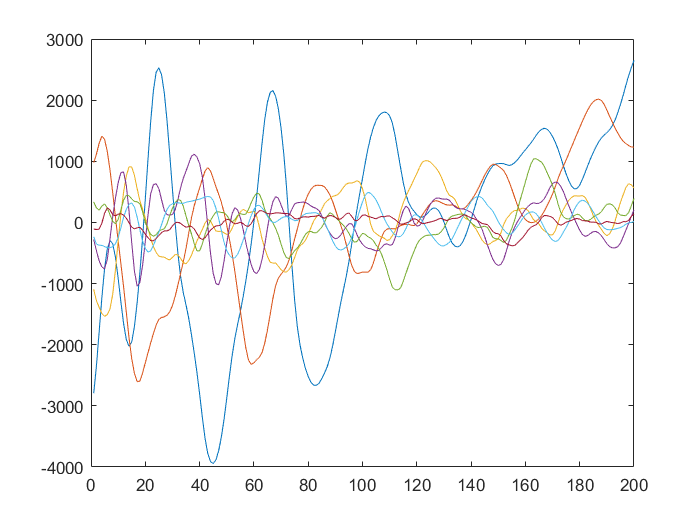



plot(score(:,1:7))

We then look at 200 ms before the goal signal 

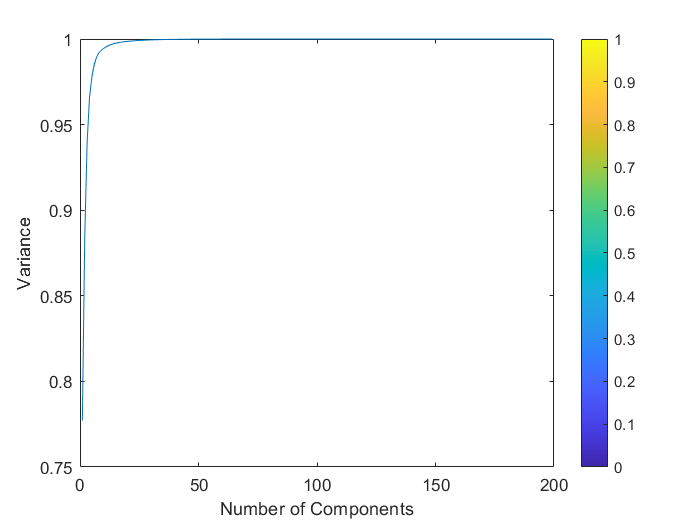

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'TargsOn';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;


driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32

dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;

driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);

data_twoDrives{2} = data;
% we are gonna compress the data
data_two_drives_aftergo = cat(2,data_twoDrives{1},data_twoDrives{2});

%then we do PCA

ti = 4;
data_temp = squeeze(data_two_drives_aftergo(ti,:,:));
[coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables

plot(cumsum(latent)/sum(latent))
xlabel('Number of Components')
ylabel('Variance')
colorbar

cal_eff_dim(latent);

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'TargsOn';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;


driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32

dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;

driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);

data_twoDrives{2} = data;
% we are gonna compress the data
data_two_drives_afterTargsOn = cat(2,data_twoDrives{1},data_twoDrives{2});



% this time 200 ms after Reach Start 
trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32

dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;
driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{2} = data;
% we are gonna compress the data
data_two_drives_afterReachStart = cat(2,data_twoDrives{1},data_twoDrives{2});

then we need to compare

for ti = 1:length(Trials)

    data_temp = squeeze(data_two_drives_aftergo(ti,:,:));
    [coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables
    dims(1,ti) = cal_eff_dim(latent);
    
    data_temp = squeeze(data_two_drives_afterTargsOn(ti,:,:));
    [coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables
    dims(2,ti) = cal_eff_dim(latent);
    
    data_temp = squeeze(data_two_drives(ti,:,:));
    [coeff,score,latent]  = pca(data_temp');
    dims(3,ti) = cal_eff_dim(latent);
    
    data_temp = squeeze(data_two_drives_afterReachStart(ti,:,:));
    [coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables
    dims(4,ti) = cal_eff_dim(latent);
    
end

disp('Done')

Done


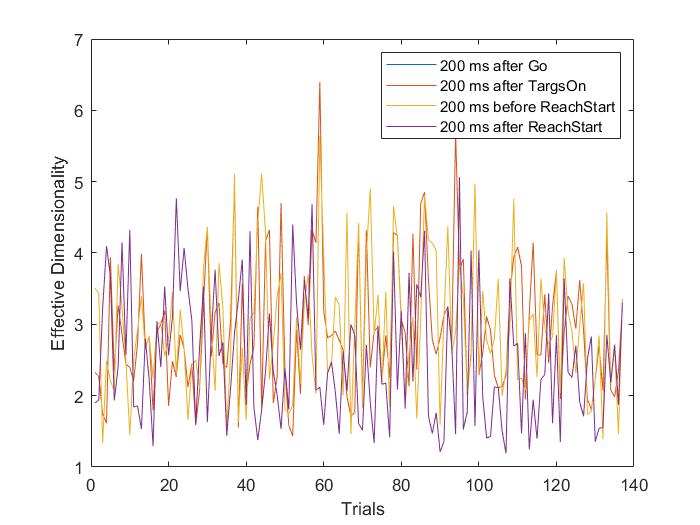

plot(dims')
xlabel('Trials')
ylabel('Effective Dimensionality')
legend('200 ms after Go','200 ms after TargsOn','200 ms before ReachStart','200 ms after ReachStart')

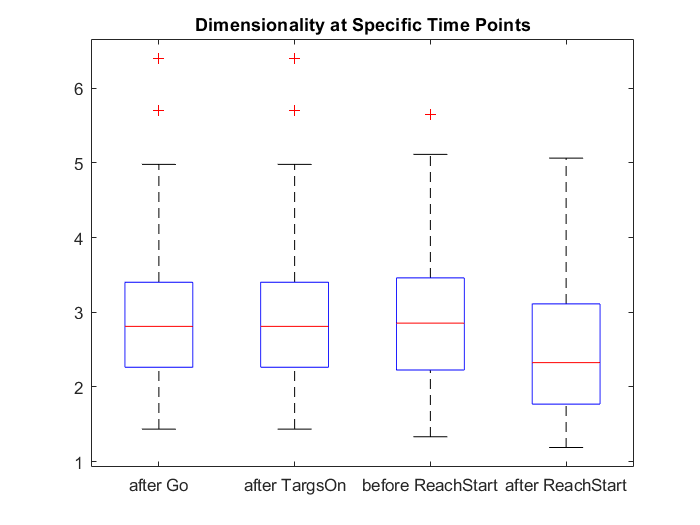

% try another way to plot the data
figure
boxplot(dims','Labels', {'after Go','after TargsOn','before ReachStart','after ReachStart'})
title('Dimensionality at Specific Time Points')

Now, we can try to divide the recordings into different targets.

trialInfo.tBefore = -2e2;
trialInfo.tAfter  = 0;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;

driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{2} = data;
%sort the matrix
dataTarget_cell = mulSortTrials_cell(data_twoDrives{1},trial_TargetAssigned, Trials);
dataTarget_SC32_cell = mulSortTrials_cell(data_twoDrives{2},trial_TargetAssigned, Trials);

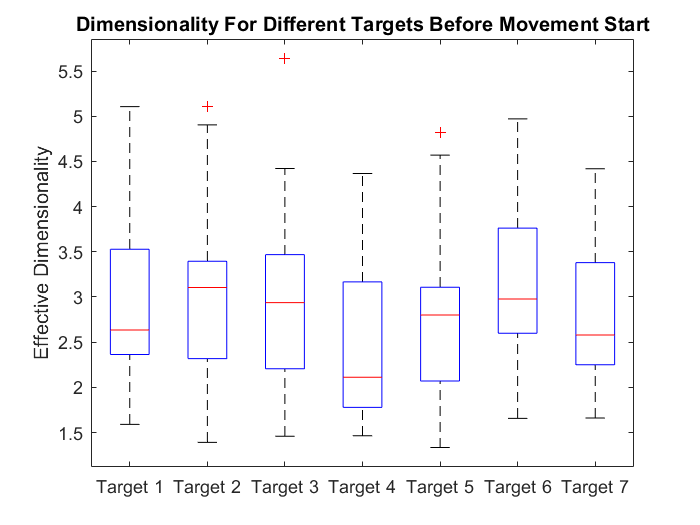

%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    data_2 = dataTarget_SC32_cell{targ_i};
    
    data = cat(2,data,data_2);
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets Before Movement Start')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

Then we can compare this just before 

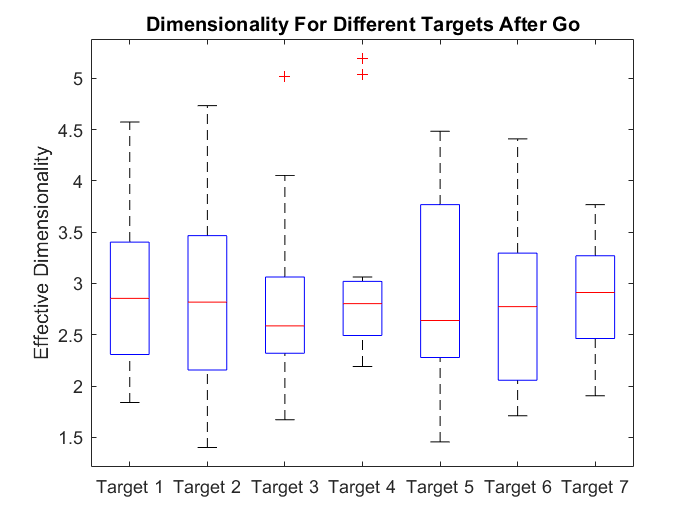

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'Go';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;

driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{2} = data;

%sort the matrix
dataTarget_cell = mulSortTrials_cell(data_twoDrives{1},trial_TargetAssigned, Trials);
dataTarget_SC32_cell = mulSortTrials_cell(data_twoDrives{2},trial_TargetAssigned, Trials);

%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    data_2 = dataTarget_SC32_cell{targ_i};
    
    data = cat(2,data,data_2);
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After Go')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

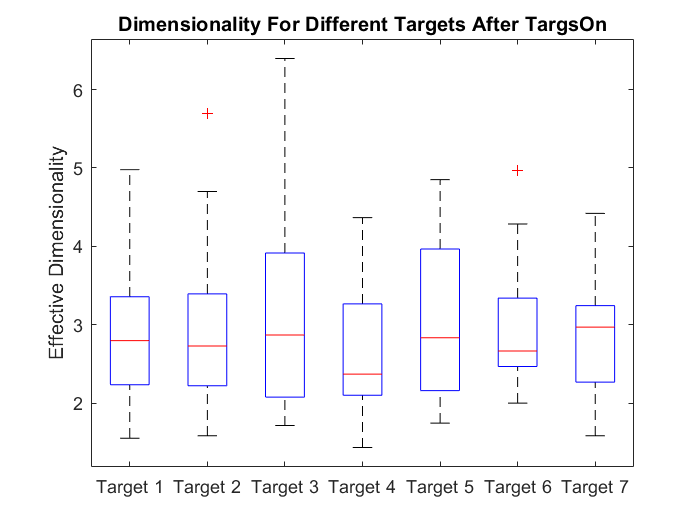

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'TargsOn';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

data_twoDrives = load_trials(Trials,trialInfo,experiment,MONKEYDIR);

%sort the matrix
dataTarget_cell = mulSortTrials_cell(data_twoDrives{1},trial_TargetAssigned, Trials);
dataTarget_SC32_cell = mulSortTrials_cell(data_twoDrives{2},trial_TargetAssigned, Trials);


%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    data_2 = dataTarget_SC32_cell{targ_i};
    
    data = cat(2,data,data_2);
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After TargsOn')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

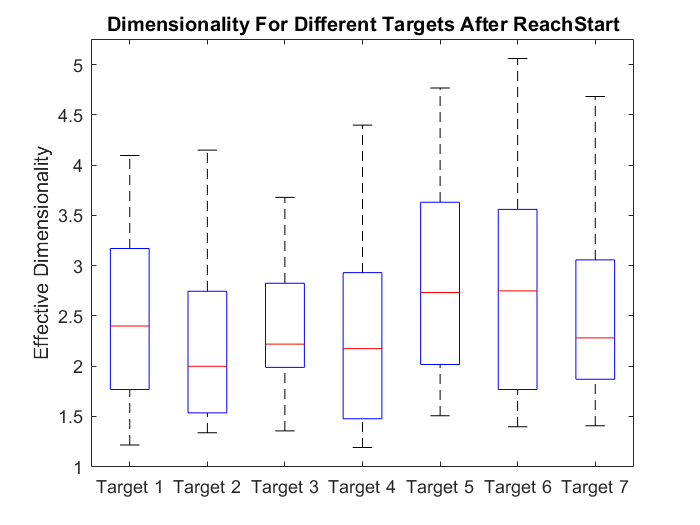

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

data_twoDrives = load_trials(Trials,trialInfo,experiment,MONKEYDIR);
%sort the matrix
dataTarget_cell = mulSortTrials_cell(data_twoDrives{1},trial_TargetAssigned, Trials);
dataTarget_SC32_cell = mulSortTrials_cell(data_twoDrives{2},trial_TargetAssigned, Trials);

%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    data_2 = dataTarget_SC32_cell{targ_i};
    
    data = cat(2,data,data_2);
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After ReachStart')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

% combine the trials
Trials = [Trials_1838,Trials_1839];

trialInfo.tBefore = 0;
trialInfo.tAfter  = 2e2;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

data_twoDrives_1 = load_trials(Trials_1838,trialInfo,experiment,MONKEYDIR);
data_twoDrives_2 = load_trials(Trials_1839,trialInfo,experiment,MONKEYDIR);

data_twoDrives_ECOG = cat(1,data_twoDrives_1{1},data_twoDrives_2{1});
data_twoDrives_SC32 = cat(1,data_twoDrives_1{2},data_twoDrives_2{2});

data_twoDrives = cat(2,data_twoDrives_ECOG,data_twoDrives_SC32);

dataTarget_cell = mulSortTrials_cell(data_twoDrives,trial_TargetAssigned, Trials);

Error using mulSortTrials_cell (line 11)
The data structure length (223) does not match the trial length (137)



%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After ReachStart')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)
% combine the trials
Trials = [Trials_1838,Trials_1839];

trialInfo.tBefore = -2e2;
trialInfo.tAfter  = 0;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

data_twoDrives_1 = load_trials(Trials_1838,trialInfo,experiment,MONKEYDIR);
data_twoDrives_2 = load_trials(Trials_1839,trialInfo,experiment,MONKEYDIR);

data_twoDrives_ECOG = cat(1,data_twoDrives_1{1},data_twoDrives_2{1});
data_twoDrives_SC32 = cat(1,data_twoDrives_1{2},data_twoDrives_2{2});

data_twoDrives = cat(2,data_twoDrives_ECOG,data_twoDrives_SC32);

dataTarget_cell = mulSortTrials_cell(data_twoDrives,trial_TargetAssigned, Trials);


%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After ReachStart')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

% combine the trials
Trials = Trials_1839;

trialInfo.tBefore = -2e2;
trialInfo.tAfter  = 0;
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

data_twoDrives_1 = load_trials(Trials,trialInfo,experiment,MONKEYDIR);

data_twoDrives_ECOG = data_twoDrives_1{1};
data_twoDrives_SC32 = data_twoDrives_1{2};
data_twoDrives = cat(2,data_twoDrives_ECOG,data_twoDrives_SC32);
dataTarget_cell = mulSortTrials_cell(data_twoDrives,trial_TargetAssigned, Trials);


%now calculate PCA
g = [];
for targ_i = 1:7
    data = dataTarget_cell{targ_i};
    dim_target_row{targ_i}= cal_trial_PCA(data);
    
    %figure out the grouping 
    g = [g;targ_i*ones(size(data,1),1)];
end

%figure out grouping

figure
boxplot(cell2mat(dim_target_row),g,'Labels', {'Target 1','Target 2','Target 3','Target 4','Target 5','Target 6','Target 7'})
title('Dimensionality For Different Targets After ReachStart')
ylabel('Effective Dimensionality')
set(gca,'FontSize',11)

function dim_eff = cal_eff_dim(latent)
lamda_j = latent / sum(latent);
dim_eff = 1 / sum(lamda_j.^2);
end

function dim_row = cal_trial_PCA(data)
%input trial * electrodes * time series
trial_n = size(data,1);

for ti = 1:trial_n
    
    data_temp = squeeze(data(ti,:,:));
    [coeff,score,latent]  = pca(data_temp'); %the rows are observations, and the columns are variables
    dim_row(1,ti) = cal_eff_dim(latent);
    
end
end

function data_twoDrives = load_trials(Trials,trialInfo,experiment,MONKEYDIR)


driveNameAnalyze = 'LM1_ECOG_3';
drive_idx = 1; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
data_twoDrives{1} = data;

driveNameAnalyze = 'LM1_SC32_1';
drive_idx = 2; %1 for ECOG and 2 for SC32
dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
data = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);

data_twoDrives{2} = data;
end